# Exponential Growth

Suppose a population at time $t$ is $N(t)$

and for a small time interval $h$, the change in population can be written as:


$$N(t + h) = N(t) + \Delta (N, h)$$


Now, we have two assumptions:

- When $h = 0$, $\Delta (N, h) = \Delta (N, 0) = 0$

- When $N = 0$, i.e., there is no population left, $\Delta (0, h) = 0$

With these assumptions in mind, we can express the change in population using the current population $N$, the time interval $h$ and a constant $r_c$ which can be interpreted as the "per-capita growth rate" (per-capita means per-individual).


$$\Delta (N, h) = r_c Nh$$


Now, if $h \to 0$, we can write the differential $\frac{dN}{dt} = r_c Nh$

Solving this differential, we get to the expression:

$N(t) = N_0 e^{r_ct}$ where $N_0 = N(0)$ 

Say, we are given

rc = 0.8;
N0 = 50;

and we want to observe for a span of 500 time points.

t = linspace(0,5,500);

We can write our expression:

N_exp = N0*exp(rc*t);

And we can plot this!

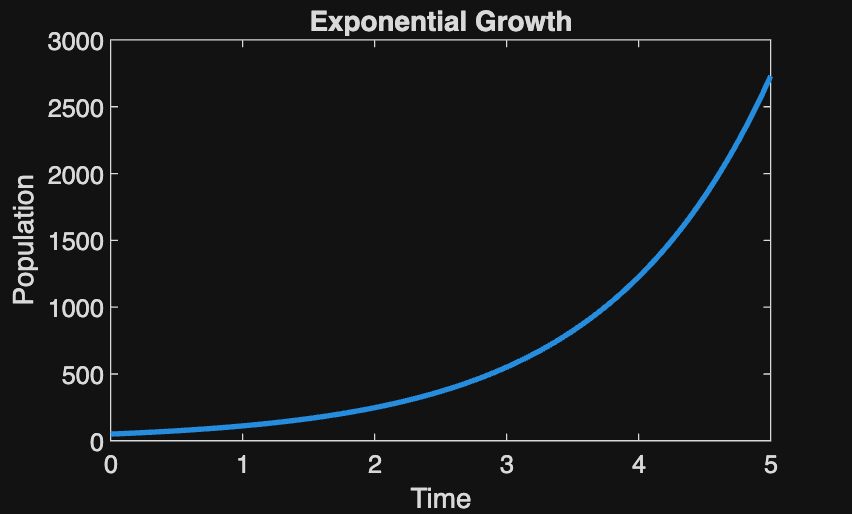

plot(t,N_exp,'LineWidth',2); 
hold on;
xlabel('Time'); ylabel('Population');
title('Exponential Growth');

# Logistic Growth

Often, exponential growth is unrealistic. Think of a bacterial population - it cannot grow forever! The environment needs to supply the sufficient food, space and other stuff for the bacteria to survive too. This is why populations, after a burst of exponential growth, halt down to a steady state - which is the maximum the environment can support.

We represent the population size an environment can sustain as its **carrying capacity **$K$.

We can assume that the per-capita growth rate $r_c$ decreases linearly as the population grows in size and becomes zero at the carrying capacity $K$.

This can be expressed as:


$$\frac{1}{N}\frac{dN}{dt} = r_c (1 - \frac{N}{K})$$


Multiplying N by both sides,


$$\frac{dN}{dt} = Nr_c(1 - \frac{N}{K})$$


we get the **logistic differential equation**.

Solving this differential, we can get to the analytical logistic solution


$$N(t) = \frac{K}{1 + \left(\frac{K-N_0}{N_0}\right)e^{-r_c t}}$$


Now, given

K  = 1000;        % carrying capacity

We can write the expression:

N_log = K ./ (1 + ((K-N0)/N0).*exp(-rc*t));

And we can plot this too!

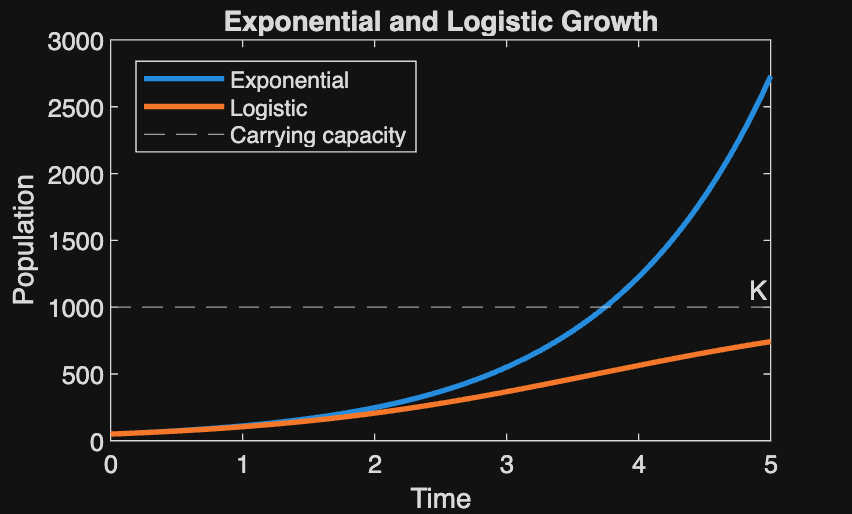

plot(t,N_log,'LineWidth',2);
yline(K,'--','K');
title('Exponential and Logistic Growth');
legend('Exponential','Logistic','Carrying capacity','Location','best');